# Motion control SPLINES

Andrés Holguín Restrepo

2023-1

clear
close all

ni=9;
nf=30;


t = linspace(0,2*pi,ni);
tf=linspace(t(1),t(end),nf)

tf =              0          0.22          0.43          0.65          0.87          1.08          1.30          1.52          1.73          1.95          2.17          2.38          2.60          2.82          3.03          3.25          3.47          3.68          3.90          4.12          4.33          4.55          4.77          4.98          5.20          5.42          5.63          5.85          6.07          6.28


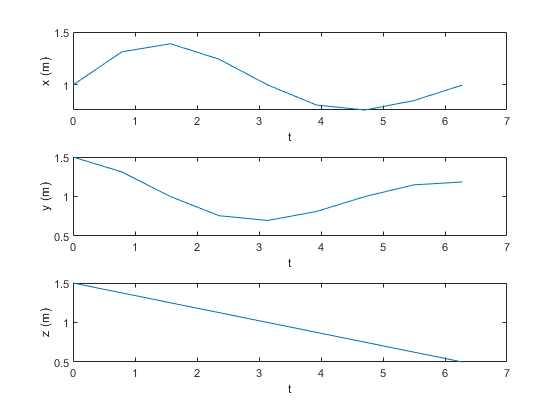

x = 1+sin(t).*0.5.*exp(-t./2/pi);
y = 1+cos(t).*0.5.*exp(-t./2/pi);
z = (2*pi-t)/2/pi+0.5;



subplot(3,1,1)
plot(t,x)
ylabel("x (m)")
xlabel("t")
subplot(3,1,2)
plot(t,y)
ylabel("y (m)")
xlabel("t")
subplot(3,1,3)
plot(t,z)
ylabel("z (m)")
xlabel("t")



data=[x' y' z']

data =           1.00          1.50          1.50
          1.31          1.31          1.38
          1.39          1.00          1.25
          1.24          0.76          1.13
          1.00          0.70          1.00
          0.81          0.81          0.88
          0.76          1.00          0.75
          0.85          1.15          0.63
          1.00          1.18          0.50





xx=spline(t,x,tf);
yy=spline(t,y,tf);
zz=spline(t,z,tf);
format bank
data=[(1:30)' xx' yy' zz']

data =           1.00          1.00          1.50          1.50
          2.00          1.11          1.47          1.47
          3.00          1.20          1.42          1.43
          4.00          1.27          1.36          1.40
          5.00          1.33          1.28          1.36
          6.00          1.37          1.20          1.33
          7.00          1.39          1.11          1.29
          8.00          1.39          1.02          1.26
          9.00          1.37          0.94          1.22
         10.00          1.34          0.86          1.19


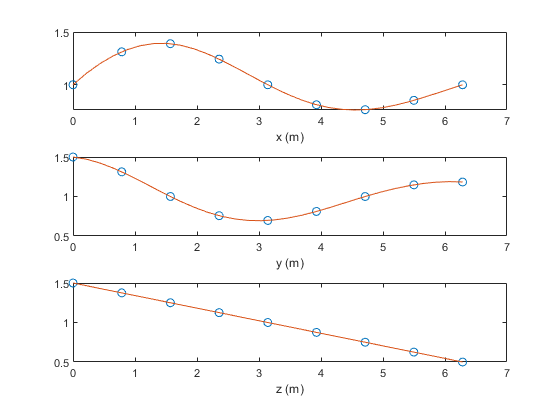



figure()

subplot(3,1,1)
plot(t,x,'o',tf,xx)
xlabel("x (m)")
subplot(3,1,2)
plot(t,y,'o',tf,yy)
xlabel("y (m)")
subplot(3,1,3)
plot(t,z,'o',tf,zz)
xlabel("z (m)")

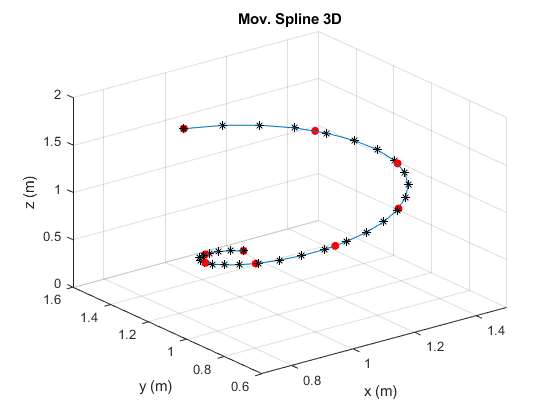


figure()
%line(x,y,z,'Color','red','LineStyle','--')

scatter3(x,y,z,'filled',"o","MarkerFaceColor","red")
hold on
scatter3(xx,yy,zz,"*","black")
line(xx,yy,zz)
hold off
xlabel("x (m)");
ylabel("y (m)");
zlabel("z (m)");
view(120,50);
grid on
title("Mov. Spline 3D")
hold off
view(3)
axis([0.7 1.5 0.6 1.6 0 2]);

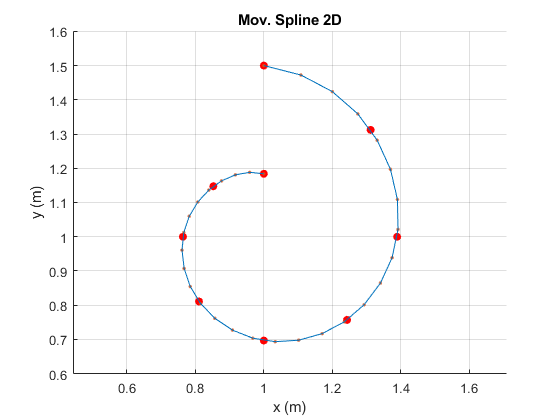

figure()
scatter(x,y,'filled',"o","MarkerFaceColor","red")
hold on
scatter(xx,yy,".","MarkerFaceColor","black")
line(xx,yy)
hold off
xlabel("x (m)");
ylabel("y (m)");
axis([0.7 1.5 0.6 1.6]);
axis equal
grid on
title("Mov. Spline 2D")


pp = spline(t,sqrt(x.^2+y.^2))

pp = struct with fields:
      form: 'pp'
    breaks: [0 0.79 1.57 2.36 3.14 3.93 4.71 5.50 6.28]
     coefs: [8×4 double]
    pieces: 8.00
     order: 4.00
       dim: 1.00


rhoSPLINE = ppval(pp, linspace(0,2*pi,101))

rhoSPLINE =           1.80          1.82          1.83          1.84          1.85          1.85          1.86          1.86          1.86          1.86          1.86          1.86          1.86          1.85          1.85          1.84          1.83          1.82          1.81          1.80          1.79          1.77          1.76          1.75          1.73          1.71          1.69          1.68          1.66          1.64          1.62          1.60          1.57          1.55          1.53          1.51          1.49          1.47          1.44          1.42          1.40          1.38          1.36          1.34          1.32          1.30          1.28          1.26          1.25          1.23


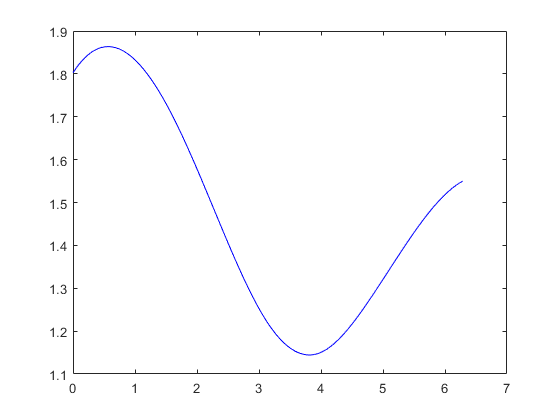

plot(linspace(0,2*pi,101),rhoSPLINE,'-b')

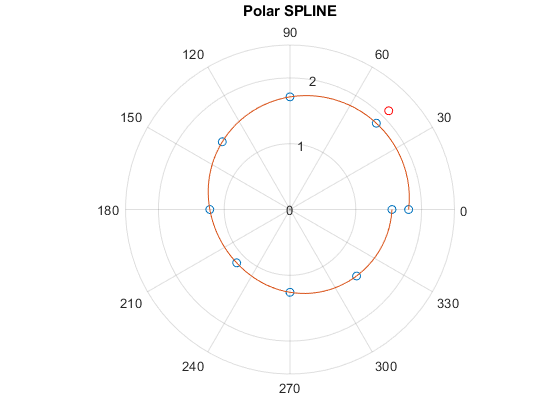

polarplot(t,sqrt(x.^2+y.^2),'o')
hold on
polarplot(linspace(0,2*pi,101),rhoSPLINE)
polarplot(pi/4,1.5*sqrt(2),'r-o')
hold off
title("Polar SPLINE")

### Tipos de interpolación

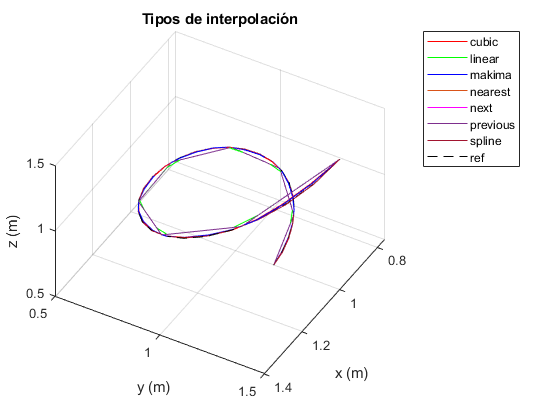

figure()
line(interp1(t,x,tf,"cubic"),interp1(t,y,tf,"cubic"),interp1(t,z,tf,"cubic"),'Color','red','LineWidth',0.25)
hold on
line(interp1(t,x,tf,"linear"),interp1(t,y,tf,"linear"),interp1(t,z,tf,"linear"),'Color','green','LineWidth',0.25)
line(interp1(t,x,tf,"makima"),interp1(t,y,tf,"makima"),interp1(t,z,tf,"makima"),'Color','blue','LineWidth',0.25)
line(interp1(t,x,tf,"nearest"),interp1(t,y,tf,"nearest"),interp1(t,z,tf,"nearest"),'Color','#D95319','LineWidth',0.25)
line(interp1(t,x,tf,"next"),interp1(t,y,tf,"next"),interp1(t,z,tf,"next"),'Color','magenta','LineWidth',0.25)
line(interp1(t,x,tf,"previous"),interp1(t,y,tf,"previous"),interp1(t,z,tf,"previous"),'Color','#7E2F8E','LineWidth',0.25)
line(interp1(t,x,tf,"spline"),interp1(t,y,tf,"spline"),interp1(t,z,tf,"spline"),'Color','#A2142F','LineWidth',0.25)
plot3(1+0.5*sin(tf).*exp(-tf./2/pi),1+0.5*cos(tf).*exp(-tf./2/pi),(2*pi-tf)/2/pi+0.5,"k--")
hold off
view(120,50);
xlabel("x (m)");
ylabel("y (m)");
zlabel("z (m)");
title("Tipos de interpolación")
legend("cubic","linear","makima","nearest","next","previous","spline","ref")
grid on

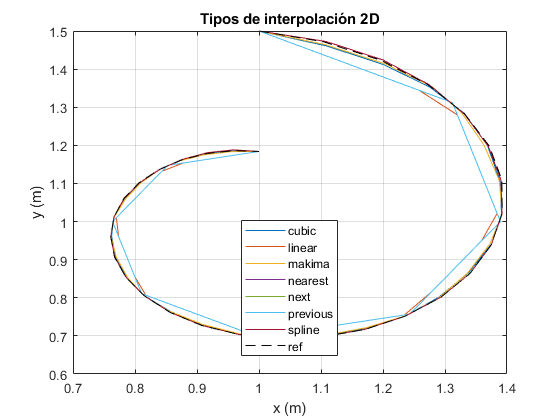







figure()
plot(interp1(t,x,tf,"cubic"),interp1(t,y,tf,"cubic"))
hold on
plot(interp1(t,x,tf,"linear"),interp1(t,y,tf,"linear"))
plot(interp1(t,x,tf,"makima"),interp1(t,y,tf,"makima"))
plot(interp1(t,x,tf,"nearest"),interp1(t,y,tf,"nearest"))
plot(interp1(t,x,tf,"next"),interp1(t,y,tf,"next"))
plot(interp1(t,x,tf,"previous"),interp1(t,y,tf,"previous"))
plot(interp1(t,x,tf,"spline"),interp1(t,y,tf,"spline"))
plot(1+0.5*sin(tf).*exp(-tf./2/pi),1+0.5*cos(tf).*exp(-tf./2/pi),"k--")
hold off
xlabel("x (m)");
ylabel("y (m)");

title("Tipos de interpolación 2D")
legend("cubic","linear","makima","nearest","next","previous","spline","ref","Location","best")
%legend("cubic","spline")
grid on

Error

x_ref=1+0.5*sin(tf).*exp(-tf./2/pi)

x_ref =           1.00          1.10          1.20          1.27          1.33          1.37          1.39          1.39          1.37          1.34          1.29          1.24          1.17          1.10          1.03          0.97          0.91          0.86          0.82          0.79          0.77          0.76          0.77          0.78          0.81          0.84          0.88          0.92          0.96          1.00


y_ref=1+0.5*cos(tf).*exp(-tf./2/pi)

y_ref =           1.50          1.47          1.42          1.36          1.28          1.20          1.11          1.02          0.94          0.86          0.80          0.75          0.72          0.70          0.69          0.70          0.73          0.76          0.80          0.85          0.91          0.96          1.01          1.06          1.10          1.14          1.16          1.18          1.19          1.18


z_ref=(2*pi-tf)/2/pi+0.5

z_ref =           1.50          1.47          1.43          1.40          1.36          1.33          1.29          1.26          1.22          1.19          1.16          1.12          1.09          1.05          1.02          0.98          0.95          0.91          0.88          0.84          0.81          0.78          0.74          0.71          0.67          0.64          0.60          0.57          0.53          0.50


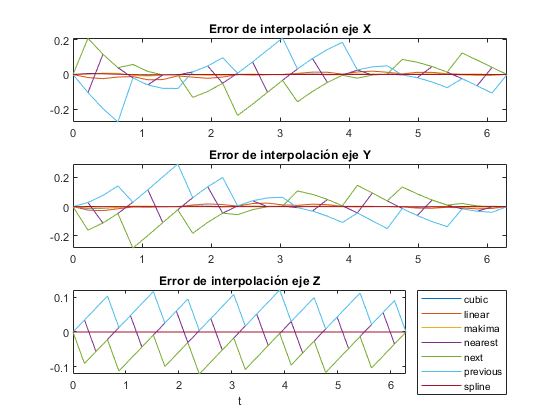



figure
subplot(3,1,1)
plot(tf,interp1(t,x,tf,"cubic")-x_ref)
hold on
plot(tf,interp1(t,x,tf,"linear")-x_ref)
plot(tf,interp1(t,x,tf,"makima")-x_ref)
plot(tf,interp1(t,x,tf,"nearest")-x_ref)
plot(tf,interp1(t,x,tf,"next")-x_ref)
plot(tf,interp1(t,x,tf,"previous")-x_ref)
plot(tf,interp1(t,x,tf,"spline")-x_ref)
hold off
xlim([0 2*pi])
title("Error de interpolación eje X")
%legend("cubic","linear","makima","nearest","next","previous","spline","Location","best")

subplot(3,1,2)
plot(tf,interp1(t,y,tf,"cubic")-y_ref)
hold on
plot(tf,interp1(t,y,tf,"linear")-y_ref)
plot(tf,interp1(t,y,tf,"makima")-y_ref)
plot(tf,interp1(t,y,tf,"nearest")-y_ref)
plot(tf,interp1(t,y,tf,"next")-y_ref)
plot(tf,interp1(t,y,tf,"previous")-y_ref)
plot(tf,interp1(t,y,tf,"spline")-y_ref)
hold off
xlim([0 2*pi])
title("Error de interpolación eje Y")
%legend("cubic","linear","makima","nearest","next","previous","spline","Location","best")

subplot(3,1,3)
plot(tf,interp1(t,z,tf,"cubic")-z_ref)
hold on
plot(tf,interp1(t,z,tf,"linear")-z_ref)
plot(tf,interp1(t,z,tf,"makima")-z_ref)
plot(tf,interp1(t,z,tf,"nearest")-z_ref)
plot(tf,interp1(t,z,tf,"next")-z_ref)
plot(tf,interp1(t,z,tf,"previous")-z_ref)
plot(tf,interp1(t,z,tf,"spline")-z_ref)
hold off
xlim([0 2*pi])
title("Error de interpolación eje Z")
legend("cubic","linear","makima","nearest","next","previous","spline","Location","bestoutside")
xlabel("t")

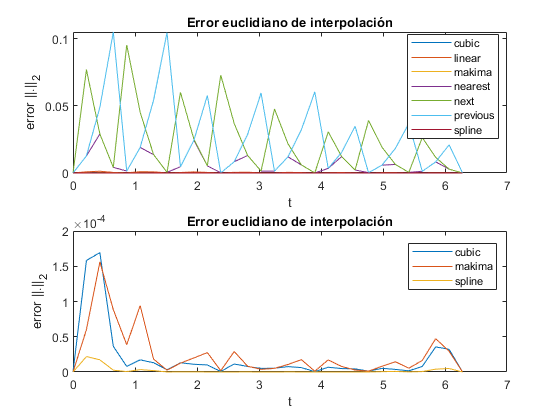


figure
subplot(2,1,1)
plot(tf,(interp1(t,x,tf,"cubic")-x_ref).^2+(interp1(t,y,tf,"cubic")-y_ref).^2+(interp1(t,z,tf,"cubic")-z_ref).^2)
hold on
plot(tf,(interp1(t,x,tf,"linear")-x_ref).^2+(interp1(t,y,tf,"linear")-y_ref).^2+(interp1(t,z,tf,"linear")-z_ref).^2)
plot(tf,(interp1(t,x,tf,"makima")-x_ref).^2+(interp1(t,y,tf,"makima")-y_ref).^2+(interp1(t,z,tf,"makima")-z_ref).^2)
plot(tf,(interp1(t,x,tf,"nearest")-x_ref).^2+(interp1(t,y,tf,"nearest")-y_ref).^2+(interp1(t,z,tf,"nearest")-z_ref).^2)
plot(tf,(interp1(t,x,tf,"next")-x_ref).^2+(interp1(t,y,tf,"next")-y_ref).^2+(interp1(t,z,tf,"next")-z_ref).^2)
plot(tf,(interp1(t,x,tf,"previous")-x_ref).^2+(interp1(t,y,tf,"previous")-y_ref).^2+(interp1(t,z,tf,"previous")-z_ref).^2)
plot(tf,(interp1(t,x,tf,"spline")-x_ref).^2+(interp1(t,y,tf,"spline")-y_ref).^2+(interp1(t,z,tf,"spline")-z_ref).^2)
hold off
legend
title("Error euclidiano de interpolación")
legend("cubic","linear","makima","nearest","next","previous","spline","Location","best")
ylabel("error ||.||_2")
xlabel("t")

subplot(2,1,2)
plot(tf,(interp1(t,x,tf,"cubic")-x_ref).^2+(interp1(t,y,tf,"cubic")-y_ref).^2+(interp1(t,z,tf,"cubic")-z_ref).^2)
hold on
plot(tf,(interp1(t,x,tf,"makima")-x_ref).^2+(interp1(t,y,tf,"makima")-y_ref).^2+(interp1(t,z,tf,"makima")-z_ref).^2)
plot(tf,(interp1(t,x,tf,"spline")-x_ref).^2+(interp1(t,y,tf,"spline")-y_ref).^2+(interp1(t,z,tf,"spline")-z_ref).^2)
hold off
ylabel("error ||.||_2")
xlabel("t")
legend
title("Error euclidiano de interpolación")
legend("cubic","makima","spline","Location","best")

Errores spline

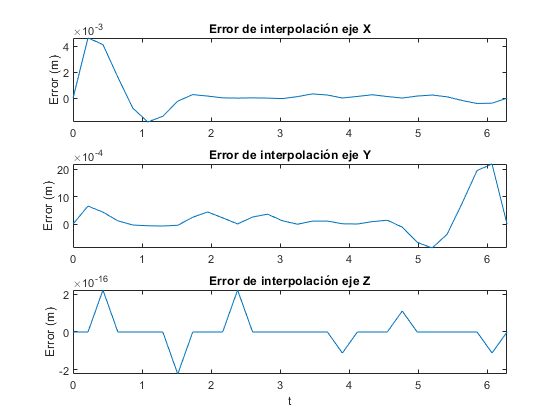

figure
subplot(3,1,1)
plot(tf,interp1(t,x,tf,"spline")-x_ref)
ylabel("Error (m)")
xlim([0 2*pi])
title("Error de interpolación eje X")
%legend("cubic","linear","makima","nearest","next","previous","spline","Location","best")

subplot(3,1,2)
plot(tf,interp1(t,y,tf,"spline")-y_ref)
xlim([0 2*pi])
ylabel("Error (m)")
title("Error de interpolación eje Y")
%legend("cubic","linear","makima","nearest","next","previous","spline","Location","best")

subplot(3,1,3)

plot(tf,interp1(t,z,tf,"spline")-z_ref)

xlim([0 2*pi])
ylabel("Error (m)")
title("Error de interpolación eje Z")
%legend("spline","Location","best")
xlabel("t")

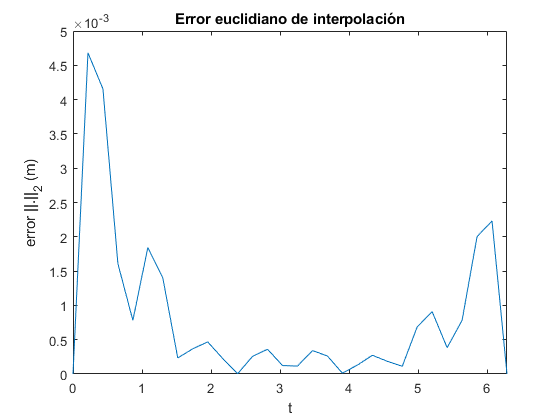


figure
plot(tf,sqrt((interp1(t,x,tf,"spline")-x_ref).^2+(interp1(t,y,tf,"spline")-y_ref).^2+(interp1(t,z,tf,"spline")-z_ref).^2))
hold off
xlim([0 2*pi])
title("Error euclidiano de interpolación")

%legend("spline","Location","best")
ylabel("error ||.||_2 (m)")
xlabel("t")

## SOLUCIÓN MAYA_UN

startup_rvc

H=3

H =           3.00


D=2.2

D =           2.20


delta=0.3

delta =           0.30



[L0,L1,L2,L3,thetas]=soluciones(xx,yy,zz,H,D,delta);


## SIMULACIÓN MAYA_UN

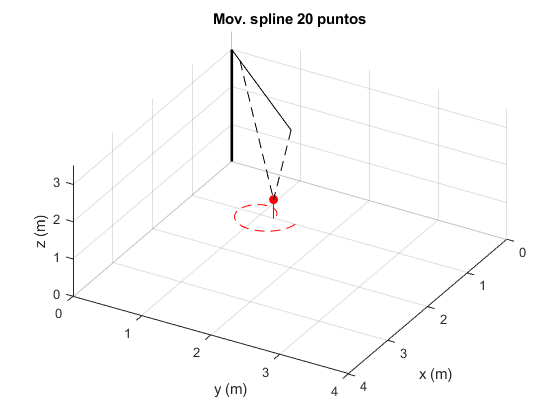

figure()
for i=1:length(xx)
    clf
    stem3(xx(i),yy(i),zz(i),"ro",'filled')
    line(xx(1:i),yy(1:i),'Color','red','LineStyle','--')
    line(L0(:,1,i),L0(:,2,i),L0(:,3,i),'Color','black','LineWidth',2)
    line(L1(:,1,i),L1(:,2,i),L1(:,3,i),'Color','black')
    line(L2(:,1,i),L2(:,2,i),L2(:,3,i),'Color','black','LineStyle','--')
    line(L3(:,1,i),L3(:,2,i),L3(:,3,i),'Color','black','LineStyle','--')
    view(120,50);
    axis([0 4 0 4 0 3.5]);
    xlabel("x (m)");
    ylabel("y (m)");
    zlabel("z (m)");
    grid on
    title("Mov. spline 20 puntos")
    %w = waitforbuttonpress;
    F(i) = getframe(gcf) ;
    drawnow
end


writerObj = VideoWriter('Caso20p',"MPEG-4");
writerObj.FrameRate = 10;

open(writerObj);

for i=1:length(F)
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
close(writerObj);

## Resultados reales

Vals=[99.2	151.3;110.5	148.9;119.5	143.9;128.4	138.4;133.9	129.6;137.3	122.3;139.1	112.8;138.8	102.9;136.7	94.2;133.4	85.4;127.8	78.9;122.7	73.7;114.8	70.5;107.6	68.4;100.0	67.6;94.4	68.9;88.5	71.8;83.2	75.4;79.5	79.3;76.9	84.5;75.1	91.0;73.9	96.6;75.8	102.2;77.4	107.4;80.7	112.2;84.4	116.5;89.2	118.4;93.6	120.5;98.2	121.3;101.1	120.2]/100

Vals =           0.99          1.51
          1.10          1.49
          1.20          1.44
          1.28          1.38
          1.34          1.30
          1.37          1.22
          1.39          1.13
          1.39          1.03
          1.37          0.94
          1.33          0.85


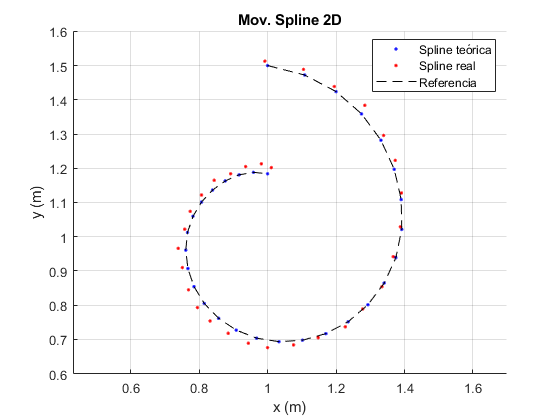



figure()
%scatter(x,y,'filled',"o","MarkerFaceColor","red")
scatter(xx,yy,".","MarkerEdgeColor","blue")
hold on
scatter(Vals(:,1),Vals(:,2),".","MarkerEdgeColor","red")
plot(xx,yy,'k--')
hold off
xlabel("x (m)");
ylabel("y (m)");
axis([0.7 1.5 0.6 1.6]);
axis equal
grid on
legend("Spline teórica","Spline real","Referencia","Location","best")
title("Mov. Spline 2D")

Errores

Errores spline

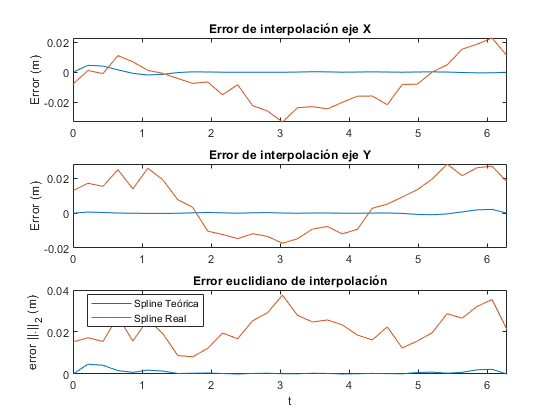

figure
subplot(3,1,1)
plot(tf,interp1(t,x,tf,"spline")-x_ref)
hold on
plot(tf,Vals(:,1)'-x_ref)
hold off
ylabel("Error (m)")
xlim([0 2*pi])
title("Error de interpolación eje X")
%legend("Spline Teórica","Spline Real","Location","best")

subplot(3,1,2)
plot(tf,interp1(t,y,tf,"spline")-y_ref)
hold on
plot(tf,Vals(:,2)'-y_ref)
hold off
xlim([0 2*pi])
ylabel("Error (m)")
title("Error de interpolación eje Y")
%legend("Spline Teórica","Spline Real","Location","best")
%legend("cubic","linear","makima","nearest","next","previous","spline","Location","best")

subplot(3,1,3)
plot(tf,sqrt((interp1(t,x,tf,"spline")-x_ref).^2+(interp1(t,y,tf,"spline")-y_ref).^2))
hold on
plot(tf,sqrt((Vals(:,1)'-x_ref).^2+(Vals(:,2)'-y_ref).^2))
hold off
legend("Spline Teórica","Spline Real","Location","best")
title("Error euclidiano de interpolación")

%legend("spline","Location","best")
ylabel("error ||.||_2 (m)")
xlabel("t")
xlim([0 2*pi])

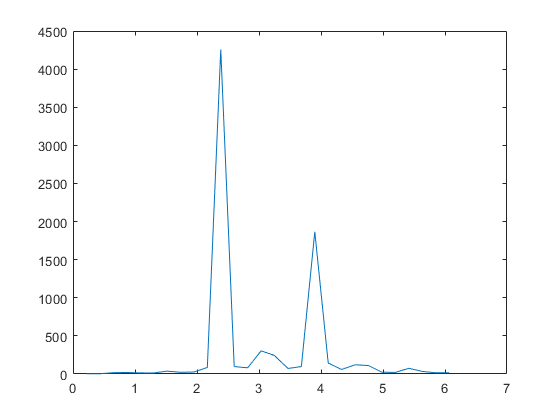

figure
plot(tf,sqrt((Vals(:,1)'-x_ref).^2+(Vals(:,2)'-y_ref).^2)./sqrt((interp1(t,x,tf,"spline")-x_ref).^2+(interp1(t,y,tf,"spline")-y_ref).^2))

errorR=sqrt((Vals(:,1)'-x_ref).^2+(Vals(:,2)'-y_ref).^2)./sqrt((interp1(t,x,tf,"spline")-x_ref).^2+(interp1(t,y,tf,"spline")-y_ref).^2)

errorR =            Inf          3.69          3.72         17.06         20.05         14.06         13.73         37.54         22.34         26.09         85.97       4257.82         97.97         80.97        304.43        242.48         72.49         97.94       1866.38        142.99         59.40        120.98        110.91         22.80         21.60         74.91         33.92         16.06         15.89           Inf


mean(errorR(2:end-1))

ans =         281.58


function [L0,L1,L2,L3,thetas]=soluciones(x,y,z,H,D,delta)
    for i=1:length(x)
        [L0_i,L1_i,L2_i,L3_i,thetas_i]=solMaya(x(i),y(i),z(i),H,D,delta);
        thetas(i,:)=thetas_i;
        L0(:,:,i)=L0_i;L1(:,:,i)=L1_i;
        L2(:,:,i)=L2_i;L3(:,:,i)=L3_i;
    end
end


function [L0,L1,L2,L3,thetas]=solMaya(x,y,z,H,D,delta)
    syms theta_2 theta_3
    [theta,rho,z] = cart2pol(x,y,z);
    h=z-H;
    b=sqrt((rho-delta)^2+h^2);
    c=sqrt((rho-D)^2+h^2);
    F1=0==sin(theta_3)/b-sin(theta_2)/c;
    F2=D==delta+b*cos(theta_2)+c*cos(theta_3);
    [SolTheta_2,SolTheta_3]=vpasolve([F1;F2],[theta_2;theta_3],[pi/4,pi/4]);
    SolTheta_2=-double(SolTheta_2);
    SolTheta_3=-double(SolTheta_3);
    P0=[0,0,0];
    P1=P0+[0,0,H];
    P1_2=P1+[delta,0,0]*rotz(-theta);
    P2=P1+[D,0,0]*rotz(-theta);
    P3=P1_2+[b,0,0]*roty(SolTheta_2)*rotz(-theta);
    L0=[P0;P1];L1=[P1;P2];L2=[P1_2;P3];L3=[P2;P3];
    thetas=[theta,SolTheta_2,SolTheta_3];
end

